## 先進プラズマ理工学 report  2023/5/17

clear all;

%パラメータ設定
R0 = 3; %[m]
B = 2; %[T]
q = 3; 
r = 0.4*R0; %[m]
ev2j = 1.602e-19; % 1[ev] = 1.602e-19[J]
k_Ti = 3e3*ev2j; %[J]
mi = 2.01*1.66e-27; %1個あたりの重さ
qe = 1.602e-19; %[C]

%パラメータ変更
step = 1000;
max_nu = 60000;
nu = linspace(1,max_nu,step);


% thermal velocity of ion
vthi = sqrt(k_Ti/mi)

vthi = 3.7952e+05

omega_ci = qe*B/mi; %電荷q=1 
rci = vthi/omega_ci

rci = 0.0040


% nu_psとnu_bのindex求める
nu_ps = vthi/(q*R0)

nu_ps = 4.2169e+04

nu_b = (r/R0).^1.5*vthi/(q*R0)

nu_b = 1.0668e+04

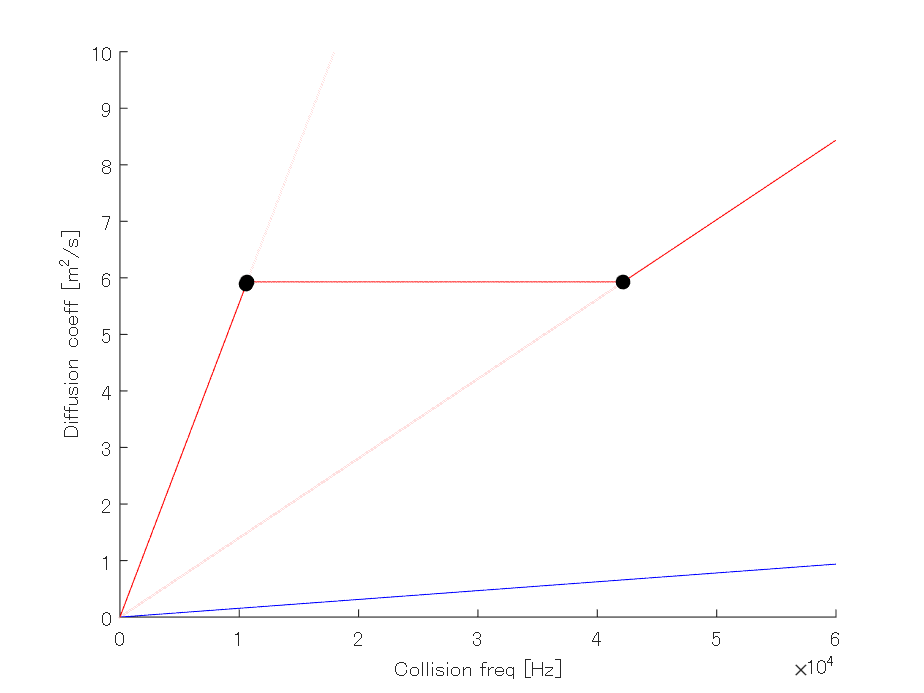

%古典拡散係数
Dcl = rci.^2*nu;

%新古典拡散
Db = (R0/r).^1.5*q.^2*rci.^2*nu;
Dp = q.^2*rci.^2*nu_ps*ones(length(nu));
Dps = q.^2*rci.^2*nu;


nu_b_ind = find(abs(nu-nu_b)< 50);
nu_ps_ind = find(abs(nu-nu_ps) < 50);


figure;
hold on
plot(nu, Dcl,'b')

plot(nu(1:nu_b_ind),Db(1:nu_b_ind),'r')
plot(nu(nu_b_ind:end),Db(nu_b_ind:end),'*r','MarkerSize',0.01)

plot(nu(nu_b_ind:nu_ps_ind),Dp(nu_b_ind:nu_ps_ind),'r')

plot(nu(nu_ps_ind:end),Dps(nu_ps_ind:end),'r')
plot(nu(1:nu_ps_ind),Dps(1:nu_ps_ind),'*r','MarkerSize',0.01)

plot(nu(nu_ps_ind),Dps(nu_ps_ind),'.k','MarkerSize',20)
plot(nu(nu_b_ind),Db(nu_b_ind),'.k','MarkerSize',20)

xlabel('Collision freq [Hz]')
ylabel('Diffusion coeff [m^2/s]')
ylim([0,10])
hold off